## **DART results**

i2067 (membrane tdTomato-HTP), i2070 (membrane tdTomato-HTP) , and i2100 (NucExcluded-tdTomato-HTP) YM90K DART.

Cells included per mouse at each contrast (inclusion criteria: matched, responsive on at least one day, has running and stationary trials at preferred direction):

cellCountTableRed

cellCountTableRed = 3×1 table
             cellCountsRed 
             ______________

    i2067     9     3     3
    i2070     6     6     6
    i2100    10    10    10


cellCountTableGreen

cellCountTableGreen = 3×1 table
             cellCountsGreen
             _______________

    i2067    39    14    15 
    i2070    82    82    82 
    i2100    62    62    62 


### Timecourses

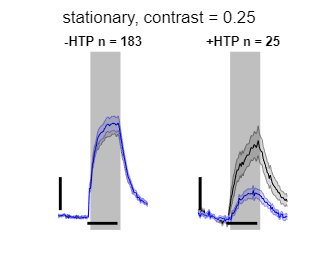

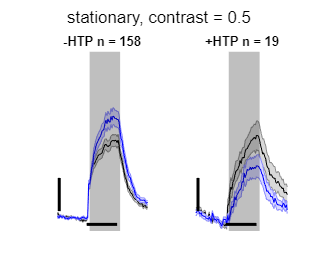

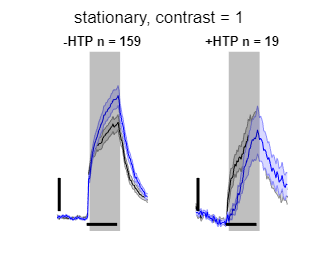

%% for the cells that have stationary and running

% make figure with se shaded, one figure per contrast - stationary

tc_green_avrg_stat = cell(1,nd); %this will be the average across all green cells - a single line
tc_red_avrg_stat = cell(1,nd); %same for red
tc_green_se_stat = cell(1,nd); %this will be the se across all green cells
tc_red_se_stat = cell(1,nd); %same for red



for id = 1:nd
    for iCon=1:nCon
        
    tc_green_avrg_stat{id}(:,iCon)=nanmean(tc_trial_avrg_stat_concat{id}(:,haveRunning_green{iCon},iCon),2);
    green_std=nanstd(tc_trial_avrg_stat_concat{id}(:,haveRunning_green{iCon},iCon),[],2);
    tc_green_se_stat{id}(:,iCon)=green_std/sqrt(length(haveRunning_green{iCon}));
    
    tc_red_avrg_stat{id}(:,iCon)=nanmean(tc_trial_avrg_stat_concat{id}(:,haveRunning_red{iCon},iCon),2);
    red_std=nanstd(tc_trial_avrg_stat_concat{id}(:,haveRunning_red{iCon},iCon),[],2);
    tc_red_se_stat{id}(:,iCon)=red_std/sqrt(length(haveRunning_red{iCon}));
    
    clear green_std red_std
    end
end
z=double(nOn)/double(frame_rate);

%create a time axis in seconds
t=1:(size(tc_green_avrg_stat{1,1,1},1));
t=(t-(double(stimStart)-1))/double(frame_rate);

for iCon = 1:nCon
figure
subplot(1,2,1) %for the first day



ylim([-.02 .25]);;
hold on
shadedErrorBar(t,tc_green_avrg_stat{pre}(:,iCon),tc_green_se_stat{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,tc_green_avrg_stat{post}(:,iCon),tc_green_se_stat{post}(:,iCon),'b','transparent');
hold on
line([0,z],[-.01,-.01],'Color','black','LineWidth',2);
fill([0.2 0.2 (z+.2) (z+.2)],[-.02 .25 .25 -.02],'k',FaceAlpha = 0.25,LineStyle='none')
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
title(['-HTP',' n = ', num2str(length(haveRunning_green{iCon}))])

ylabel('dF/F') 
xlabel('s') 
set(gca,'XColor', 'none','YColor','none')


subplot(1,2,2) %for the second day
shadedErrorBar(t,tc_red_avrg_stat{pre}(:,iCon),tc_red_se_stat{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,tc_red_avrg_stat{post}(:,iCon),tc_red_se_stat{post}(:,iCon),'b');
ylim([-.02 .25]);;
hold on
line([0,z],[-.01,-.01],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
ylabel('dF/F') 
xlabel('s') 
fill([0.2 0.2 (z+.2) (z+.2)],[-.02 .25 .25 -.02],'k',FaceAlpha = 0.25,LineStyle='none')
title(['+HTP',' n = ', num2str(length(haveRunning_red{iCon}))])

x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])
set(gca,'XColor', 'none','YColor','none')

sgtitle(['stationary, contrast = ' num2str(cons(iCon))])

%print(fullfile(fnout,[num2str(cons(iCon)) '_stat_cellType_timecourses.pdf']),'-dpdf');
end 

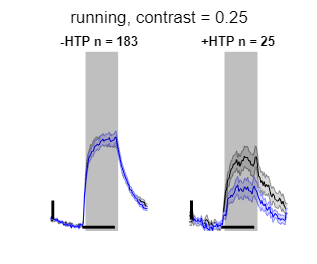

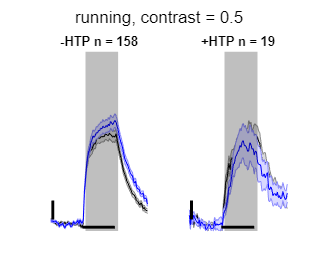

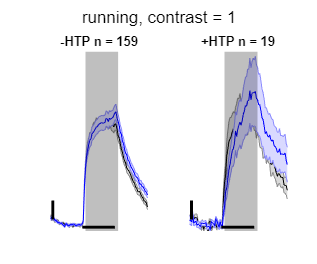


%% shaded error tc for loc

tc_green_avrg_loc = cell(1,nd); %this will be the average across all green cells - a single line
tc_red_avrg_loc = cell(1,nd); %same for red
tc_green_se_loc = cell(1,nd); %this will be the se across all green cells
tc_red_se_loc = cell(1,nd); %same for red

for id = 1:nd
    for iCon=1:nCon
    tc_green_avrg_loc{id}(:,iCon)=nanmean(tc_trial_avrg_loc_concat{id}(:,haveRunning_green{iCon},iCon),2);
    green_std=nanstd(tc_trial_avrg_loc_concat{id}(:,haveRunning_green{iCon},iCon),[],2);
    tc_green_se_loc{id}(:,iCon)=green_std/sqrt(length(haveRunning_green{iCon}));
    
    tc_red_avrg_loc{id}(:,iCon)=nanmean(tc_trial_avrg_loc_concat{id}(:,haveRunning_red{iCon},iCon),2);
    red_std=nanstd(tc_trial_avrg_loc_concat{id}(:,haveRunning_red{iCon},iCon),[],2);
    tc_red_se_loc{id}(:,iCon)=red_std/sqrt(length(haveRunning_red{iCon}));
    
    clear green_std red_std
    end
end


%creat a time axis in seconds
t=1:(size(tc_green_avrg_loc{1,1,1},1));
t=(t-(double(stimStart)-1))/double(frame_rate);


for iCon = 1:nCon
figure
subplot(1,2,1) %for the first day
shadedErrorBar(t,tc_green_avrg_loc{pre}(:,iCon),tc_green_se_loc{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,tc_green_avrg_loc{post}(:,iCon),tc_green_se_loc{post}(:,iCon),'b');
ylim([-.02 .45]);;
hold on
line([0,z],[-.01,-.01],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
hold on
fill([0.2 0.2 (z+.2) (z+.2)],[-.02 .45 .45 -.02],'k',FaceAlpha = 0.25,LineStyle='none')
title(['-HTP',' n = ', num2str(length(haveRunning_green{iCon}))])
ylabel('dF/F') 
xlabel('s') 
set(gca,'XColor', 'none','YColor','none')


subplot(1,2,2) %for the second day
shadedErrorBar(t,tc_red_avrg_loc{pre}(:,iCon),tc_red_se_loc{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,tc_red_avrg_loc{post}(:,iCon),tc_red_se_loc{post}(:,iCon),'b');
ylim([-.02 .45]);;
hold on
line([0,z],[-.01,-.01],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
hold on
fill([0.2 0.2 (z+.2) (z+.2)],[-.02 .45 .45 -.02],'k',FaceAlpha = 0.25,LineStyle='none')
ylabel('dF/F') 
xlabel('s') 
title(['+HTP',' n = ', num2str(length(haveRunning_red{iCon}))])
x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])
set(gca,'XColor', 'none','YColor','none')

sgtitle(['running, contrast = ' num2str(cons(iCon))])
%print(fullfile(fnout,[num2str(cons(iCon)) '_loc_cellType_timecourses.pdf']),'-dpdf');
end 

clear txt1 txt2

### Scatters 

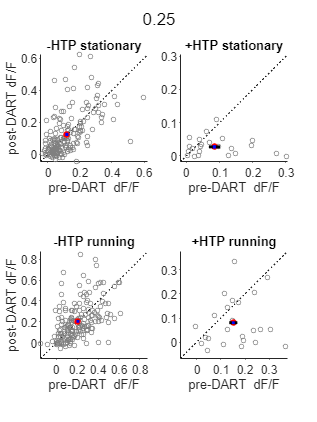

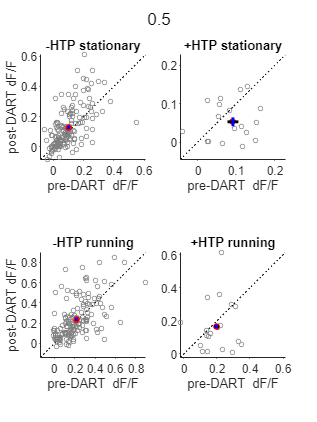

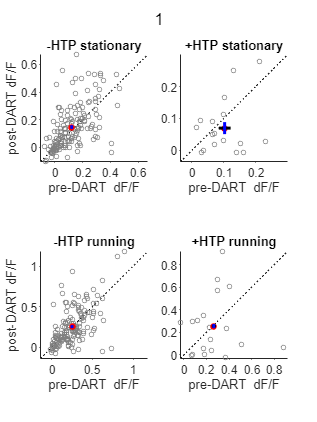

%% scatterplot of max df/f for day 1 vs day 2, and each subplot is one cell type
green_ex_list=[]; %to highlight particular cells
red_ex_list=[];

for iCon = 1:nCon
figure; movegui('center') 
subplot(2,2,1)
scatter((pref_responses_stat_concat{pre}(haveRunning_green{iCon},iCon)),(pref_responses_stat_concat{post}(haveRunning_green{iCon},iCon)),10,'MarkerEdgeColor',[.5 .5 .5],'jitter', 'on', 'jitterAmount',.01)
hold on
mean_pre_stat = nanmean(pref_responses_stat_concat{pre}(haveRunning_green{iCon},iCon));
mean_post_stat = nanmean(pref_responses_stat_concat{post}(haveRunning_green{iCon},iCon));
scatter(mean_pre_stat,mean_post_stat,20,'r','filled');
stderror_pre= std(pref_responses_stat_concat{pre}(haveRunning_green{iCon},iCon)) / sqrt( length(haveRunning_green{iCon}));
stderror_post= std(pref_responses_stat_concat{post}(haveRunning_green{iCon},iCon)) / sqrt( length(haveRunning_green{iCon}));
line([(mean_pre_stat-stderror_pre),(mean_pre_stat+stderror_pre)],[mean_post_stat, mean_post_stat],'Color','black','LineWidth',2);
line([mean_pre_stat, mean_pre_stat],[(mean_post_stat-stderror_post),(mean_post_stat+stderror_post)],'Color','blue','LineWidth',2);
ylabel('post-DART dF/F')
xlabel('pre-DART  dF/F')
limMin=min(min(pref_responses_stat_concat{pre}(haveRunning_green{iCon},iCon)),min(pref_responses_stat_concat{post}(haveRunning_green{iCon},iCon)));
limMax=max(max(pref_responses_stat_concat{pre}(haveRunning_green{iCon},iCon)),max(pref_responses_stat_concat{post}(haveRunning_green{iCon},iCon)));
ylim([limMin limMax])
xlim([limMin limMax])
hline=refline(1);
hline.Color = 'k';
hline.LineStyle = ':';
title('-HTP stationary')
axis square
set(gca, 'TickDir', 'out')
uistack(hline,'bottom');
hold off


subplot(2,2,2)
scatter((pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon)),(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon)),10,'MarkerEdgeColor',[.5 .5 .5],'jitter', 'on', 'jitterAmount',.01)
hold on
mean_pre_stat = nanmean(pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon));
mean_post_stat = nanmean(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon));
scatter(mean_pre_stat,mean_post_stat,20,'r','filled');
stderror_pre= std(pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon)) / sqrt( length(haveRunning_red{iCon}));
stderror_post= std(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon)) / sqrt( length(haveRunning_red{iCon}));
line([(mean_pre_stat-stderror_pre),(mean_pre_stat+stderror_pre)],[mean_post_stat, mean_post_stat],'Color','black','LineWidth',2);
line([mean_pre_stat, mean_pre_stat],[(mean_post_stat-stderror_post),(mean_post_stat+stderror_post)],'Color','blue','LineWidth',2);% ylabel('post-DART dF/F')
xlabel('pre-DART  dF/F')
limMin=min(min(pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon)),min(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon)));
limMax=max(max(pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon)),max(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon)));
ylim([limMin limMax])
xlim([limMin limMax])
hline=refline(1);
hline.Color = 'k';
hline.LineStyle = ':';
set(gca, 'TickDir', 'out')
uistack(hline,'bottom');
title('+HTP stationary')
axis square
hold off

subplot(2,2,3)
scatter((pref_responses_loc_concat{pre}(haveRunning_green{iCon},iCon)),(pref_responses_loc_concat{post}(haveRunning_green{iCon},iCon)),10,'MarkerEdgeColor',[.5 .5 .5],'jitter', 'on', 'jitterAmount',.01)
hold on
mean_pre_stat = nanmean(pref_responses_loc_concat{pre}(haveRunning_green{iCon},iCon));
mean_post_stat = nanmean(pref_responses_loc_concat{post}(haveRunning_green{iCon},iCon));
scatter(mean_pre_stat,mean_post_stat,20,'r','filled');
stderror_pre= std(pref_responses_loc_concat{pre}(haveRunning_green{iCon},iCon)) / sqrt( length(haveRunning_green{iCon}));
stderror_post= std(pref_responses_loc_concat{post}(haveRunning_green{iCon},iCon)) / sqrt( length(haveRunning_green{iCon}));
line([(mean_pre_stat-stderror_pre),(mean_pre_stat+stderror_pre)],[mean_post_stat, mean_post_stat],'Color','black','LineWidth',2);
line([mean_pre_stat, mean_pre_stat],[(mean_post_stat-stderror_post),(mean_post_stat+stderror_post)],'Color','blue','LineWidth',2);
ylabel('post-DART dF/F')
xlabel('pre-DART  dF/F')
limMin=min(min(pref_responses_loc_concat{pre}(haveRunning_green{iCon},iCon)),min(pref_responses_loc_concat{post}(haveRunning_green{iCon},iCon)));
limMax=max(max(pref_responses_loc_concat{pre}(haveRunning_green{iCon},iCon)),max(pref_responses_loc_concat{post}(haveRunning_green{iCon},iCon)));
ylim([limMin limMax])
xlim([limMin limMax])
hline=refline(1);
hline.Color = 'k';
hline.LineStyle = ':';
title('-HTP running')
axis square
set(gca, 'TickDir', 'out')
uistack(hline,'bottom');
hold off

subplot(2,2,4)
scatter((pref_responses_loc_concat{pre}(haveRunning_red{iCon},iCon)),(pref_responses_loc_concat{post}(haveRunning_red{iCon},iCon)),10,'MarkerEdgeColor',[.5 .5 .5],'jitter', 'on', 'jitterAmount',.01)
hold on
mean_pre_stat = nanmean(pref_responses_loc_concat{pre}(haveRunning_red{iCon},iCon));
mean_post_stat = nanmean(pref_responses_loc_concat{post}(haveRunning_red{iCon},iCon));
scatter(mean_pre_stat,mean_post_stat,20,'r','filled');
stderror_pre= std(pref_responses_stat_concat{pre}(haveRunning_red{iCon},iCon)) / sqrt( length(haveRunning_red{iCon}));
stderror_post= std(pref_responses_stat_concat{post}(haveRunning_red{iCon},iCon)) / sqrt( length(haveRunning_red{iCon}));
line([(mean_pre_stat-stderror_pre),(mean_pre_stat+stderror_pre)],[mean_post_stat, mean_post_stat],'Color','black','LineWidth',2);
line([mean_pre_stat, mean_pre_stat],[(mean_post_stat-stderror_post),(mean_post_stat+stderror_post)],'Color','blue','LineWidth',2);
xlabel('pre-DART  dF/F')
limMin=min(min(pref_responses_loc_concat{pre}(haveRunning_red{iCon},iCon)),min(pref_responses_loc_concat{post}(haveRunning_red{iCon},iCon)));
limMax=max(max(pref_responses_loc_concat{pre}(haveRunning_red{iCon},iCon)),max(pref_responses_loc_concat{post}(haveRunning_red{iCon},iCon)));
ylim([limMin limMax])
xlim([limMin limMax])
hline=refline(1);
hline.Color = 'k';
hline.LineStyle = ':';
title('+HTP running')
uistack(hline,'bottom');
axis square
hold off
set(gca, 'TickDir', 'out')

x0=5;
y0=5;
width=3;
height=4;
set(gcf,'units','inches','position',[x0,y0,width,height])

sgtitle(num2str(cons(iCon)))
%print(fullfile(fnout,[num2str(cons(iCon)) 'maxResp_crossDay.pdf']),'-dpdf','-bestfit')
clear mean_pre_stat mean_post_stat stderror_post stderror_pre
end

### Direction tuning (normalized)

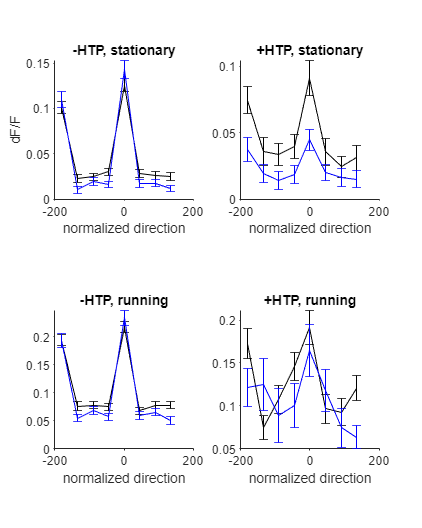

%% linear direction plot 

dirs_for_plotting=dirs-180;

green_dir_avrg_stat = cell(1,nd); %this will be the average across all green cells - a single line
red_dir_avrg_stat = cell(1,nd); %same for red
green_dir_se_stat = cell(1,nd); %this will be the se across all green cells
red_dir_se_stat = cell(1,nd); %same for red

for id = 1:nd
   
    green_dir_avrg_stat{id}=nanmean(norm_dir_resp_stat_concat{id}(green_ind_concat,:),1);
    green_std=nanstd(norm_dir_resp_stat_concat{id}(green_ind_concat,:),[],1);
    green_dir_se_stat{id}=green_std/sqrt(length(green_ind_concat));
    green_dir_avrg_stat{id}=circshift(green_dir_avrg_stat{id},4);
    green_dir_se_stat{id}=circshift(green_dir_se_stat{id},4);
    
    red_dir_avrg_stat{id}=nanmean(norm_dir_resp_stat_concat{id}(red_ind_concat,:),1);
    red_std=nanstd(norm_dir_resp_stat_concat{id}(red_ind_concat,:),[],1);
    red_dir_se_stat{id}=red_std/sqrt(length(red_ind_concat));
    red_dir_avrg_stat{id}=circshift(red_dir_avrg_stat{id},4);
    red_dir_se_stat{id}=circshift(red_dir_se_stat{id},4);
    clear green_std red_std
    
end



green_dir_avrg_loc = cell(1,nd); %this will be the average across all green cells - a single line
red_dir_avrg_loc = cell(1,nd); %same for red
green_dir_se_loc = cell(1,nd); %this will be the se across all green cells
red_dir_se_loc = cell(1,nd); %same for red

for id = 1:nd
   
    green_dir_avrg_loc{id}=nanmean(norm_dir_resp_loc_concat{id}(green_ind_concat,:),1);
    green_std=nanstd(norm_dir_resp_loc_concat{id}(green_ind_concat,:),[],1);
    green_dir_se_loc{id}=green_std/sqrt(length(green_ind_concat));
    green_dir_avrg_loc{id}=circshift(green_dir_avrg_loc{id},4);
    green_dir_se_loc{id}=circshift(green_dir_se_loc{id},4);
    
    red_dir_avrg_loc{id}=nanmean(norm_dir_resp_loc_concat{id}(red_ind_concat,:),1);
    red_std=nanstd(norm_dir_resp_loc_concat{id}(red_ind_concat,:),[],1);
    red_dir_se_loc{id}=red_std/sqrt(length(red_ind_concat));
    red_dir_avrg_loc{id}=circshift(red_dir_avrg_loc{id},4);
    red_dir_se_loc{id}=circshift(red_dir_se_loc{id},4);
    clear green_std red_std
    
end



figure
subplot(2,2,1)
errorbar(dirs_for_plotting,green_dir_avrg_stat{pre},green_dir_se_stat{pre},'k')
hold on
errorbar(dirs_for_plotting,green_dir_avrg_stat{post},green_dir_se_stat{post},'b')
title('-HTP, stationary')
set(gca, 'TickDir', 'out')
axis square
box off
ylabel('dF/F')
xlabel('normalized direction')
%ylim([0 .25])

subplot(2,2,2)
errorbar(dirs_for_plotting,red_dir_avrg_stat{pre},red_dir_se_stat{pre},'k')
hold on
errorbar(dirs_for_plotting,red_dir_avrg_stat{post},red_dir_se_stat{post},'b')
title('+HTP, stationary')
set(gca, 'TickDir', 'out')
axis square
box off
xlabel('normalized direction')
%ylim([0 .25])


subplot(2,2,3)
errorbar(dirs_for_plotting,green_dir_avrg_loc{pre},green_dir_se_loc{pre},'k')
hold on
errorbar(dirs_for_plotting,green_dir_avrg_loc{post},green_dir_se_loc{post},'b')
title('-HTP, running')
set(gca, 'TickDir', 'out')
axis square
box off
xlabel('normalized direction')
%ylim([0 .25])

subplot(2,2,4)
errorbar(dirs_for_plotting,red_dir_avrg_loc{pre},red_dir_se_loc{pre},'k')
hold on
errorbar(dirs_for_plotting,red_dir_avrg_loc{post},red_dir_se_loc{post},'b')
title('+HTP, running')
set(gca, 'TickDir', 'out')
axis square
box off
xlabel('normalized direction')
%ylim([0 .25])

x0=5;
y0=5;
width=4;
height=5;
set(gcf,'units','inches','position',[x0,y0,width,height])



%print(fullfile(fnout,['dirTuning.pdf']),'-dpdf','-bestfit')

Was preferred direction stable across days? Polar plot of difference in preferred direction.

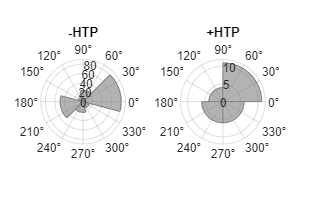

%% comparing the preferred direction across days

change_pref = pref_dir_concat{pre}-pref_dir_concat{post};
change_pref=deg2rad(change_pref);
figure
subplot(1,2,1)
polarhistogram(change_pref(green_ind_concat),'FaceColor',[.5 .5 .5],'EdgeColor',[.5 .5 .5])
title('-HTP')
set(gca, 'TickDir', 'out')

subplot(1,2,2)
polarhistogram(change_pref(red_ind_concat),'FaceColor',[.5 .5 .5],'EdgeColor',[.5 .5 .5])
title('+HTP')
set(gca, 'TickDir', 'out')

x0=5;
y0=5;
width=3;
height=2;
set(gcf,'units','inches','position',[x0,y0,width,height])

### Contrast response

Here, cells are not matched across behavioral state but should be matched across contrast.

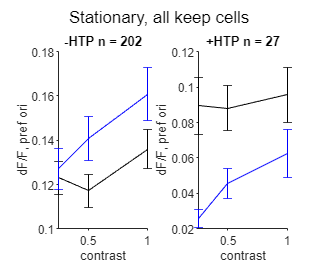

%% plot contrast response

conResp_green_avrg_stat = cell(1,nd); %this will be the average across all green cells - a single line
conResp_red_avrg_stat = cell(1,nd); %same for red
conResp_green_se_stat = cell(1,nd); %this will be the se across all green cells
conResp_red_se_stat = cell(1,nd); %same for red



for id = 1:nd
   
        
    conResp_green_avrg_stat{id}=nanmean(pref_responses_stat_concat{id}(green_ind_concat ,:),1);
    green_std=nanstd(pref_responses_stat_concat{id}(green_ind_concat,:),1);
    conResp_green_se_stat{id}=green_std/sqrt(length(green_ind_concat));
    
    conResp_red_avrg_stat{id}=nanmean(pref_responses_stat_concat{id}(red_ind_concat,:),1);
    red_std=nanstd(pref_responses_stat_concat{id}(red_ind_concat,:),1);
    conResp_red_se_stat{id}=red_std/sqrt(length(red_ind_concat));
    
    clear green_std red_std
 
end


figure
subplot(1,2,1) %for the first day
errorbar(cons,conResp_green_avrg_stat{pre},conResp_green_se_stat{pre},'k');
hold on
errorbar(cons,conResp_green_avrg_stat{post},conResp_green_se_stat{post},'b');
title(['-HTP',' n = ', num2str(length(green_ind_concat))])
ylabel('dF/F, pref ori') 
xlabel('contrast') 
set(gca, 'TickDir', 'out')
box off

subplot(1,2,2) %for the second day
errorbar(cons,conResp_red_avrg_stat{pre},conResp_red_se_stat{pre},'k');
hold on
errorbar(cons,conResp_red_avrg_stat{post},conResp_red_se_stat{post},'b');
title(['+HTP',' n = ', num2str(length(red_ind_concat))])
ylabel('dF/F, pref ori') 
xlabel('contrast') 
set(gca, 'TickDir', 'out')
box off

x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])



sgtitle(['Stationary, all keep cells' ])

print(fullfile(fnout,['contrast_resposnse.pdf']),'-dpdf');

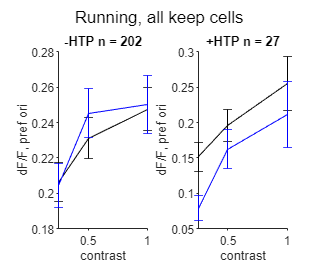




conResp_green_avrg_loc = cell(1,nd); %this will be the average across all green cells - a single line
conResp_red_avrg_loc = cell(1,nd); %same for red
conResp_green_se_loc = cell(1,nd); %this will be the se across all green cells
conResp_red_se_loc = cell(1,nd); %same for red



for id = 1:nd
   
        
    conResp_green_avrg_loc{id}=nanmean(pref_responses_loc_concat{id}(green_ind_concat ,:),1);
    green_std=nanstd(pref_responses_loc_concat{id}(green_ind_concat,:),1);
    conResp_green_se_loc{id}=green_std/sqrt(length(green_ind_concat));
    
    conResp_red_avrg_loc{id}=nanmean(pref_responses_loc_concat{id}(red_ind_concat,:),1);
    red_std=nanstd(pref_responses_loc_concat{id}(red_ind_concat,:),1);
    conResp_red_se_loc{id}=red_std/sqrt(length(red_ind_concat));
    
    clear green_std red_std
 
end


figure
subplot(1,2,1) %for the first day
errorbar(cons,conResp_green_avrg_loc{pre},conResp_green_se_loc{pre},'k');
hold on
errorbar(cons,conResp_green_avrg_loc{post},conResp_green_se_loc{post},'b');
title(['-HTP',' n = ', num2str(length(green_ind_concat))])
ylabel('dF/F, pref ori') 
xlabel('contrast') 
set(gca, 'TickDir', 'out')
box off

subplot(1,2,2) %for the second day
errorbar(cons,conResp_red_avrg_loc{pre},conResp_red_se_loc{pre},'k');
hold on
errorbar(cons,conResp_red_avrg_loc{post},conResp_red_se_loc{post},'b');
title(['+HTP',' n = ', num2str(length(red_ind_concat))])
ylabel('dF/F, pref ori') 
xlabel('contrast') 
set(gca, 'TickDir', 'out')
box off

x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])



sgtitle(['Running, all keep cells' ])

### SOM / Pyr relationship

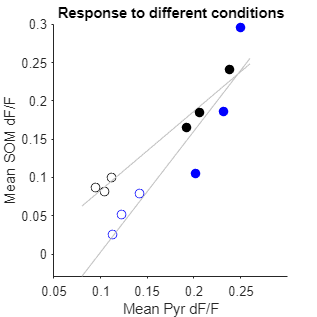

%% response by condition
%finds the cells that have running and stationary for all three contrasts
green_all = intersect(haveRunning_green{1},haveRunning_green{2});
green_all = intersect(green_all, haveRunning_green{3});

red_all = intersect(haveRunning_red{1},haveRunning_red{2});
red_all = intersect(red_all, haveRunning_red{3});


a=mean(pref_responses_stat_concat{pre}(green_all,:), "omitnan");
b=mean(pref_responses_loc_concat{pre}(green_all,:), "omitnan");

c=mean(pref_responses_stat_concat{pre}(red_all,:), "omitnan");
d=mean(pref_responses_loc_concat{pre}(red_all,:), "omitnan");

e=mean(pref_responses_stat_concat{post}(green_all,:), "omitnan");
f=mean(pref_responses_loc_concat{post}(green_all,:), "omitnan");

g=mean(pref_responses_stat_concat{post}(red_all,:), "omitnan");
h=mean(pref_responses_loc_concat{post}(red_all,:), "omitnan");

responseByCond = horzcat([a';b'],[c';d'],[e';f'],[g';h']);
clear a b c d e f g h

figure;
scatter(responseByCond(:,1),responseByCond(:,2),'k')
hold on
scatter(responseByCond(:,3),responseByCond(:,4),'b')
hold on

h2 = lsline;
hold on
scatter(responseByCond(4:6,1),responseByCond(4:6,2),'MarkerEdgeColor', 'k','MarkerFaceColor', 'k')
hold on
scatter(responseByCond(4:6,3),responseByCond(4:6,4),'MarkerEdgeColor','b','MarkerFaceColor','b')
set(gca,'TickDir','out')
xlabel('Mean Pyr dF/F')
ylabel('Mean SOM dF/F')
title('Response to different conditions')

x0=5;
y0=5;
width=3;
height=3;
set(gcf,'units','inches','position',[x0,y0,width,height])

SOM cell DART effect seperated by correlation to Pyr activity

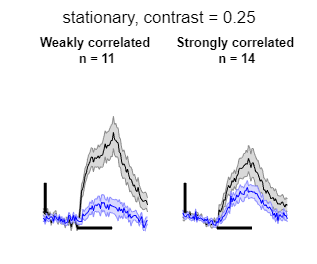

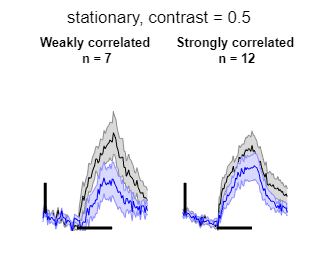

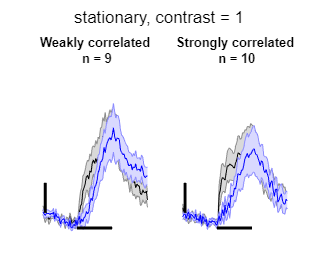

%% making tc plots for low and high R cells
highRInds=red_ind_concat(find(redR_concat)); %find the indices of red cells with high R
lowRInds=red_ind_concat(find(~redR_concat)); %find the indices of red cells with low R


%% stat high and low R
hi_avrg_stat = cell(1,nd); %this will be the average across all green cells - a single line
low_avrg_stat = cell(1,nd); %same for red
hi_se_stat = cell(1,nd); %this will be the se across all green cells
low_se_stat = cell(1,nd); %same for red


redHighN=[];
redLowN=[];
for id = 1:nd
    for iCon=1:nCon
   redHigh =  intersect(haveRunning_red{iCon},highRInds); %find intersection of red cells with high R 
   % and red cells that I have running data for on both days, for this contrast
    redLow =  intersect(haveRunning_red{iCon},lowRInds); %find intersection of red cells with low R 
   % and red cells that I have running data for on both days, for this contrast

    redHighN=[redHighN, length(redHigh)];
    redLowN=[redLowN, length(redLow)];

    hi_avrg_stat{id}(:,iCon)=nanmean(tc_trial_avrg_stat_concat{id}(:, redHigh,iCon),2);
    high_std=nanstd(tc_trial_avrg_stat_concat{id}(:, redHigh,iCon),[],2);
    hi_se_stat{id}(:,iCon)=high_std/sqrt(length(redHigh));
    
    low_avrg_stat{id}(:,iCon)=nanmean(tc_trial_avrg_stat_concat{id}(:,redLow,iCon),2);
    low_std=nanstd(tc_trial_avrg_stat_concat{id}(:, redHigh,iCon),[],2);
    low_se_stat{id}(:,iCon)=low_std/sqrt(length(redLow));
    
    clear low_std high_std redHigh redLow
    end
end
z=double(nOn)/double(frame_rate);

%creat a time axis in seconds
t=1:(size(hi_avrg_stat{1,1,1},1));
t=(t-(double(stimStart)-1))/double(frame_rate);

for iCon = 1:nCon
figure



subplot(1,2,1) 
shadedErrorBar(t,low_avrg_stat{pre}(:,iCon),low_se_stat{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,low_avrg_stat{post}(:,iCon),low_se_stat{post}(:,iCon),'b');
ylim([-.02 .25]);;
hold on
% line([0,.2],[-.01,-.01],'Color','black','LineWidth',2);
% hold on
line([0,z],[-.015,-.015],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
ylabel('dF/F') 
xlabel('s') 
title({'Weakly correlated',[' n = ', num2str(redLowN(iCon))]})
set(gca,'XColor', 'none','YColor','none')


subplot(1,2,2) 
ylim([-.02 .25]);;
hold on
shadedErrorBar(t,hi_avrg_stat{pre}(:,iCon),hi_se_stat{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,hi_avrg_stat{post}(:,iCon),hi_se_stat{post}(:,iCon),'b');
hold on
% line([0,.2],[-.01,-.01],'Color','black','LineWidth',2);
% hold on
line([0,z],[-.015,-.015],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
title({'Strongly correlated',[' n = ', num2str(redHighN(iCon))]})

xlabel('s') 
set(gca,'XColor', 'none','YColor','none')

x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])
set(gca,'XColor', 'none','YColor','none')

sgtitle(['stationary, contrast = ' num2str(cons(iCon))])

clear txt1 highRed lowRed
end 

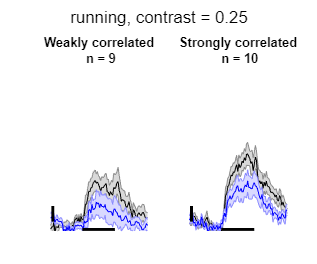

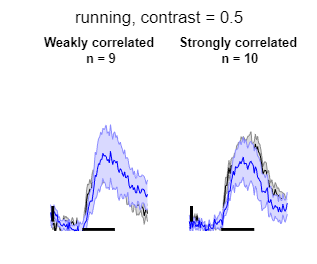

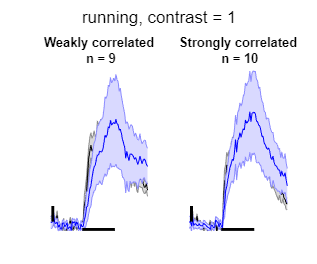


%% for running trials
highRInds=red_ind_concat(find(redR_concat)); %find the indices of red cells with high R
lowRInds=red_ind_concat(find(~redR_concat)); %find the indices of red cells with low R

hi_avrg_loc = cell(1,nd); %this will be the average across all green cells - a single line
low_avrg_loc = cell(1,nd); %same for red
hi_se_loc = cell(1,nd); %this will be the se across all green cells
low_se_loc = cell(1,nd); %same for red



for id = 1:nd
    for iCon=1:nCon
   redHigh =  intersect(haveRunning_red{iCon},highRInds); %find intersection of red cells with high R 
   % and red cells that I have running data for on both days, for this contrast
    redLow =  intersect(haveRunning_red{iCon},lowRInds); %find intersection of red cells with low R 
   % and red cells that I have running data for on both days, for this contrast

    hi_avrg_loc{id}(:,iCon)=nanmean(tc_trial_avrg_loc_concat{id}(:, redHigh,iCon),2);
    high_std=nanstd(tc_trial_avrg_loc_concat{id}(:, redHigh,iCon),[],2);
    hi_se_loc{id}(:,iCon)=high_std/sqrt(length(redHigh));
    
    low_avrg_loc{id}(:,iCon)=nanmean(tc_trial_avrg_loc_concat{id}(:,redLow,iCon),2);
    low_std=nanstd(tc_trial_avrg_loc_concat{id}(:, redHigh,iCon),[],2);
    low_se_loc{id}(:,iCon)=low_std/sqrt(length(redLow));
    
    clear low_std high_std
    end
end
z=double(nOn)/double(frame_rate);

%creat a time axis in seconds
t=1:(size(hi_avrg_loc{1,1,1},1));
t=(t-(double(stimStart)-1))/double(frame_rate);

for iCon = 1:nCon
figure

subplot(1,2,1) %for +HTP
shadedErrorBar(t,low_avrg_loc{pre}(:,iCon),low_se_loc{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,low_avrg_loc{post}(:,iCon),low_se_loc{post}(:,iCon),'b');
ylim([-.02 .5]);
hold on
line([0,z],[-.015,-.015],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
%ylabel('dF/F') 
xlabel('s') 
title({'Weakly correlated',[' n = ', num2str(length(redLow))]})
set(gca,'XColor', 'none','YColor','none')

subplot(1,2,2) 
ylim([-.02 .5]);
hold on
shadedErrorBar(t,hi_avrg_loc{pre}(:,iCon),hi_se_loc{pre}(:,iCon),'k');
hold on
shadedErrorBar(t,hi_avrg_loc{post}(:,iCon),hi_se_loc{post}(:,iCon),'b');
line([0,z],[-.015,-.015],'Color','black','LineWidth',2);
hold on
line([-1.8,-1.8],[0.01,.06],'Color','black','LineWidth',2);
title({'Strongly correlated',[' n = ', num2str(length(redHigh))]})
ylabel('dF/F') 
xlabel('s') 


x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])
set(gca,'XColor', 'none','YColor','none')

sgtitle(['running, contrast = ' num2str(cons(iCon))])


clear txt1 highRed lowRed
end 

### Suppression and facilitation of SOM cells by AMPA antagonism

Fraction of HTP+ cells that are suppressed or facilitated (> 1stdev of baseline activity) in each contrast, in the stationary condition. Cells matched across contrast.

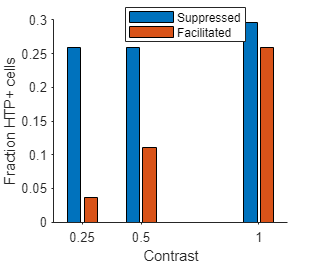

 %% bar chart of fraction red cells significantly suppressed or faciltiated
norm_diff = nan(2,nCon,nKeep_total);
for i = 1:nKeep_total
    for iCon = 1:nCon
        %for stationary trials
        mean_pre_stat = mean(pref_allTrials_stat_concat{iCon,pre}{i});
        mean_post_stat=mean(pref_allTrials_stat_concat{iCon,post}{i});
        std_pre_stat = std(pref_allTrials_stat_concat{iCon,pre}{i});
        norm_diff_stat = (mean_post_stat-mean_pre_stat) / std_pre_stat;

        %for running trials
        mean_pre_loc = mean(pref_allTrials_loc_concat{iCon,pre}{i});
        mean_post_loc=mean(pref_allTrials_loc_concat{iCon,post}{i});
        std_pre_loc = std(pref_allTrials_loc_concat{iCon,pre}{i});
        norm_diff_loc = (mean_post_loc-mean_pre_loc)/ std_pre_loc;

        %putting data into matrix
        norm_diff(1,iCon,i)=norm_diff_stat; %first is stationary
        norm_diff(2,iCon,i)=norm_diff_loc; %second is running
clear mean_pre_stat mean_post_stat std_pre_stat mean_pre_loc mean_post_loc std_pre_loc 
    end 
end
%remove any infiinty values resulting from divisions by zero, and turn
%those into NANs instead
norm_diff(find(norm_diff == -Inf))=nan;
norm_diff(find(norm_diff == Inf))=nan;

%find how many cells are suppressed ( normalized diff < -1) or facilitated
%(normalized diff >1) at each contrast and behavioral state

suppressed = logical(norm_diff < -1);
facilitated = logical(norm_diff > 1);

%pull out red cells, get fractions that are suppressed vs. favilitated,
%stationary only, using all keep cells (i.e., not only the ones that have
% %running trials
fractSupp_stat = sum((squeeze(suppressed(1,:,red_ind_concat))),2)/length(red_ind_concat);
fractFacil_stat = sum((squeeze(facilitated(1,:,red_ind_concat))),2)/length(red_ind_concat);

fractSupp_allCond = sum(squeeze(mean(suppressed(:,:,red_ind_concat),1)),2)/length(red_ind_concat);
fractFacil_allCond = sum(squeeze(mean(facilitated(:,:,red_ind_concat),1)),2)/length(red_ind_concat);

figure;
bar(cons,[fractSupp_stat,fractFacil_stat])
xticks([.25 .5 1])
ylabel(["Fraction HTP+ cells"]) 
xlabel('Contrast')
set(gca,'TickDir','out')
box off
legend('Suppressed','Facilitated')

legend("Position",[0.45425,0.85179,0.26067,0.10928])
x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])



%pull out red cells, get fractions that are suppressed vs. favilitated, for
%the red cells that have running trials at all contrasts
fractSupp_red = nan(2,3);
fractFacil_red = nan(2,3);
for iCon = 1:nCon
    fractSupp_red(:,iCon) = sum(((suppressed(:,iCon,haveRunning_red{iCon}))),3)/length(haveRunning_red{iCon});
    fractFacil_red(:,iCon) = sum(((facilitated(:,iCon,haveRunning_red{iCon}))),3)/length(haveRunning_red{iCon});
end
%averaging over contrast
supp_red = mean(fractSupp_red,2);
facil_red = mean(fractFacil_red,2);



Normalized change in each contrast, in the stationary condition (cells < -1 here are considered suppressed in barcharts above, cells 1 here are considered facilitated. Cells matched across contrast. 

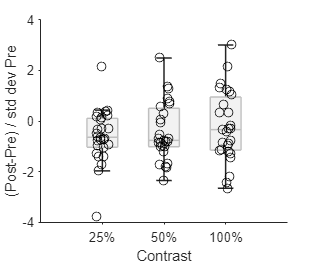


%%
figure;
boxchart(squeeze(mean(norm_diff(1,:,red_ind_concat),1))',MarkerStyle ="none",BoxFaceColor=	[.75 .75 .75]);
hold on
scatter([1 2 3],squeeze(norm_diff(1,:,red_ind_concat))',"black",'jitter', 'on', 'jitterAmount',.1)

xticklabels({'25%','50%','100%'})
xlabel('Contrast')
ylabel('(Post-Pre) / std dev Pre')
hold off
box off
set(gca,'TickDir','out')
x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])

Fraction of HTP+ cells that are suppressed or facilitated (> 1stdev of baseline activity) in each behavioral state, averaged over contrast. Cells matched across behavioral state.

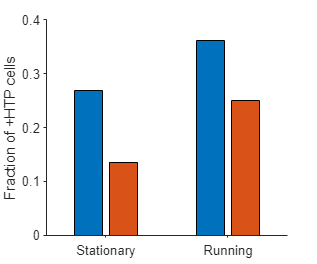

figure;
bar([supp_red, facil_red])
xticklabels({'Stationary','Running'})
box off
set(gca,'TickDir','out')
%legend('Suppressed','Facilitated')
ylabel('Fraction of +HTP cells')
x0=5;
y0=5;

width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])

Normalized change in each behavioral state, averaged over contrast. Cells matched across behavioral state.

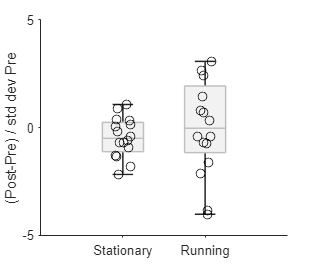

figure;
boxchart((squeeze(mean(norm_diff(:,:,red_all),2)))',MarkerStyle ="none",BoxFaceColor=	[.75 .75 .75]);hold on;
scatter([1 2],(squeeze(mean(norm_diff(:,:,red_all),2)))',"black",'jitter', 'on', 'jitterAmount',.1)
xticklabels({'Stationary','Running'})
ylabel('(Post-Pre) / std dev Pre')
ylim([-5 5])
hold off
box off
set(gca,'TickDir','out')
x0=5;
y0=5;
width=3;
height=2.5;
set(gcf,'units','inches','position',[x0,y0,width,height])